close all;clear; clc;

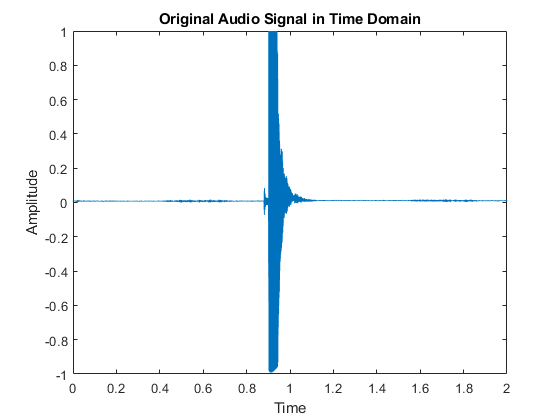

% Read the WAV file
[y, fs] = audioread('input/Sample 01.wav');
N = length(y);
tx = linspace(0, N/fs, N);


figure; 
plot(tx, y);
xlabel("Time"); ylabel("Amplitude");
title("Original Audio Signal in Time Domain");

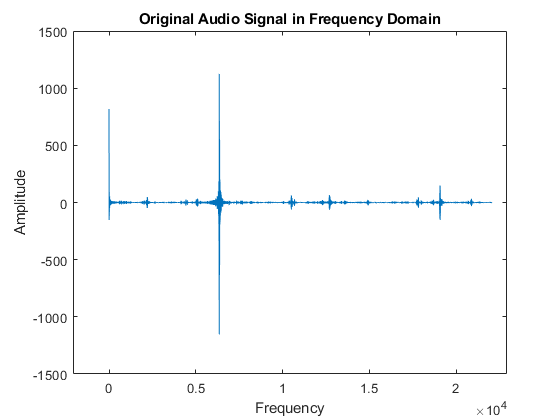

% Compute FFT
fx = linspace(0, fs, N);
Y = fft(y);

figure; 
plot(fx(1:N/2), real(Y(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Original Audio Signal in Frequency Domain");

xlim([-2074 22926])

[~, indexOfMaxValue] = max(Y);
fundamental_frequency = fx(indexOfMaxValue);
disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 6353.072 Hz


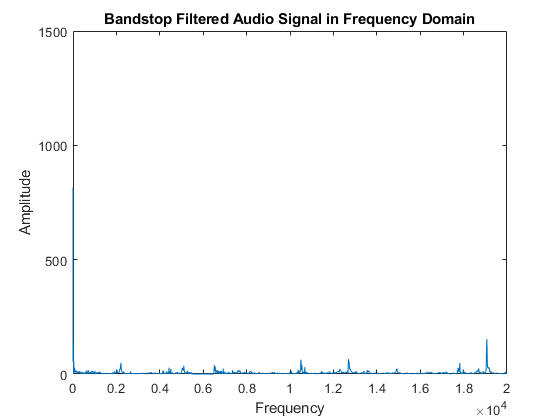

% Applying the bandstop filter
Y_cbandstop = zeros(size(Y));
cutoffLower = 5500;
cutoffUpper = 6500;
for i = 1:N
    if cutoffLower < fx(i) &&  fx(i) < cutoffUpper
        Y_cbandstop(i) = 0;
    else
        Y_cbandstop(i) = Y(i);
    end   
end


% Plot the filtered signal in the frequency domain
figure; 
plot(fx(1:N/2), abs(Y_cbandstop(1:N/2)));
xlim([0 20000]); ylim([0 1500]); 
xlabel("Frequency"); ylabel("Amplitude");
title("Bandstop Filtered Audio Signal in Frequency Domain");

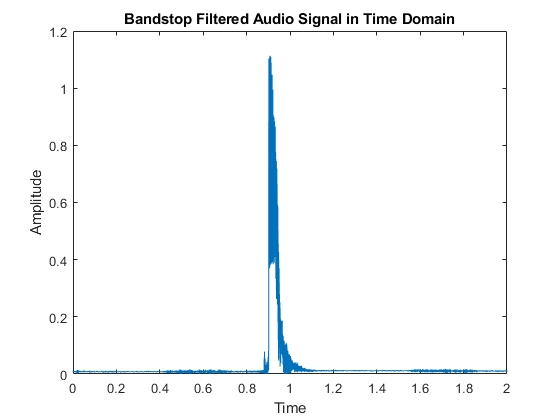

% Apply IFFT
y_cbandstop = ifft(Y_cbandstop);
figure; plot(tx, abs(y_cbandstop));
xlabel("Time"); ylabel("Amplitude");
title("Bandstop Filtered Audio Signal in Time Domain");